%clearing
clear all

%declaring symbolic functions
syms t(x) u(x)

%odes to be solved
ode1 = diff(t,x) == (2*t)/(3*x);
ode2 = diff(u,x) == 1/3;

%solving odes
dsolve(ode1)

$$ans = C_{1}\,x^{2/3}$$

dsolve(ode2)

$$ans = C_{1}+\frac{x}{3}$$

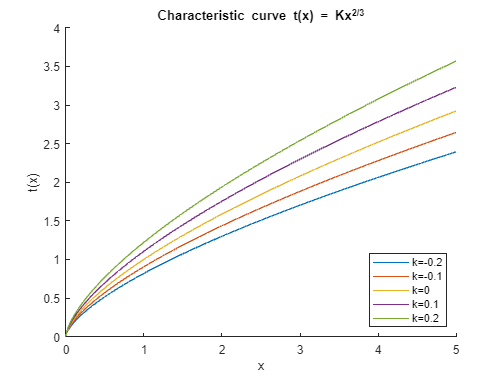

%clearing
clear all

%declaring symbolic variabless
syms t(x) K(k)

%declaring equations
K=exp(k);
t(x,k) = K*x^(2/3);
%plotting 5 graphs with different values for c
%c ranges from -0.2 to 0.2 in incriments of 0.1

%looping through values of c
for i=-.2:.1:.2
    fplot(t(x,i)) %perfoming plot
    hold on %plotting on same graph

end

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;

%plotting region of interest
xlim([0 5])
ylim([0 4])

%labelling graph
xlabel("x");
ylabel("t(x)");
title("Characteristic curve t(x) = Kx^{2/3}")
legend("k=-0.2","k=-0.1","k=0","k=0.1","k=0.2","Location","SouthEast")

hold off %end of plotting

%clearing
clear all

%declaring symbolic equations
syms u(x,t)
u(x,t) = x/3 + t/(x^(2/3)) - 1/3;

%plugging solution into original PDE
diff(u,x) + (2*t) * diff(u,t)/(3*x)

$$ans(x, t) = \frac{1}{3}$$

%clearing
clear all

%declaring symbolic equations
syms u(x,t)
u(x,t) = (t^2)/(98*x) - t/7 + x;

%plugging solution into original PDE
simplify(diff(u,x) + 7*diff(u,t) + u/x)

$$ans(x, t) = 1$$